# Introduction: Discrete Control System

## Convert a continuous-time system to its discrete equivalent

The sampling time (`Ts` in sec/sample) should be smaller than 1/(30BW), where BW is the system's closed-loop bandwidth frequency.

m = 1;
b = 10;
k = 20;

s = tf('s');
sys = 1/(m*s^2+b*s+k);

% assuming closed-loop bandwidth is 1 rad/sec
Ts = 1/100;
sys_d_tf = c2d(sys,Ts,'zoh')


sys_d_tf =
 
  4.837e-05 z + 4.678e-05
  -----------------------
  z^2 - 1.903 z + 0.9048
 
Sample time: 0.01 seconds
Discrete-time transfer function.




% state space
A = [0       1;
    -k/m   -b/m];

B = [  0;
    1/m];

C = [1 0];

D = [0];

Ts = 1/100;

sys = ss(A,B,C,D);
sys_d = c2d(sys,Ts,'zoh')


sys_d =
 
  A = 
             x1        x2
   x1     0.999  0.009513
   x2   -0.1903    0.9039
 
  B = 
              u1
   x1  4.837e-05
   x2   0.009513
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



## Stability and Transients

For analyzing the transient response from pole locations in the z-plane, the equations s used in continuous system designs in 2nd order system are still applicable.

**Important**: The natural frequency in the z-plane has units of rad/sample, but when you use the equations shown above,  must be represented in units of rad/sec

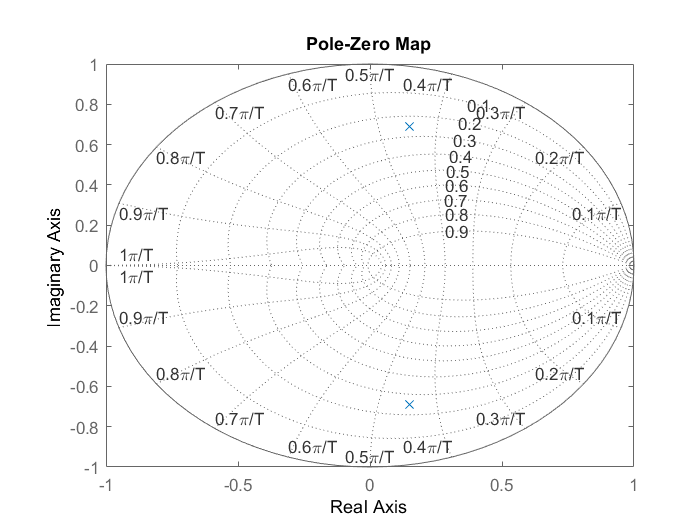

numDz = 1;
denDz = [1 -0.3 0.5];
sys = tf(numDz,denDz,0.05); 

pzmap(sys);
axis([-1 1 -1 1]);
zgrid

## Direct Root Locus

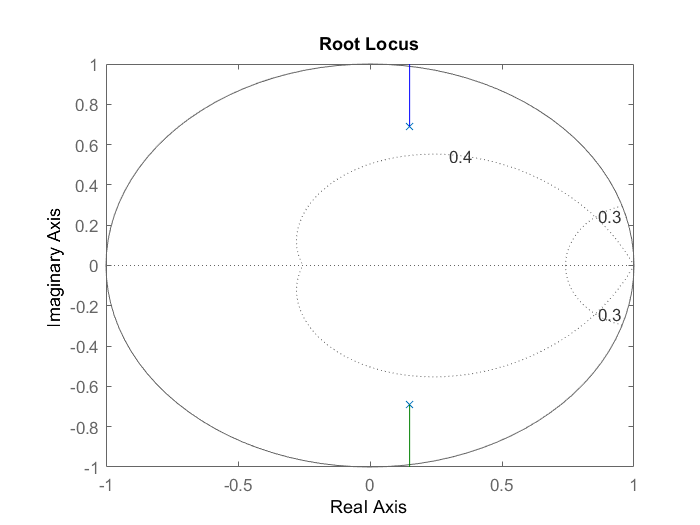

rlocus(sys)
axis([-1 1 -1 1])

zeta = 0.4;
Wn = 0.3; % wn is in rad/sample
zgrid(zeta,Wn)